# HW3 - Least-Squares Khatri-Rao Factorization (LSKRF)

### Problem 1

Let us define the matrices

$\mathit{\mathbf{X}}\in C^{20\times 4}$, which can be stated as


$$\mathit{\mathbf{X}}=\mathit{\mathbf{A}}\triangle \mathit{\mathbf{B}}$$


where $\mathit{\mathbf{A}}\in C^{5\times 4}$ and $\mathit{\mathbf{B}}\in C^{4\times 4}$ are two unknown matrices, and $\triangle$ denotes the Khatri-Rao operator.

The LSKRF is procedure that approximate $\mathit{\mathbf{X}}$ to $\hat{\mathit{\mathbf{A}}} \triangle \hat{\mathit{\mathbf{B}}}$, where $\hat{\mathit{\mathbf{A}}} \in C^{5\times 4}$ and $\hat{\mathit{\mathbf{B}}} \in C^{4\times 4}$ are the estimated values of $\mathit{\mathbf{A}}$ and $\mathit{\mathbf{B}}$, respectively.

The resulting matrices shall minimize the following cost function

${\left\|\mathit{\mathbf{X}}-\hat{\mathit{\mathbf{X}}} \right\|}_F^2$,

where $\hat{\mathit{\mathbf{X}}} =\hat{\mathit{\mathbf{A}}} \triangle \hat{\mathit{\mathbf{B}}}$ and ${\left\|\mathit{\mathbf{X}}\right\|}_F$ is the Frobenius norm of $\mathit{\mathbf{X}}$.

load krf_matrix.mat X A B

Let us $\mathit{\mathbf{X}}$ be

X

X =    -0.4407   -0.3808   -0.1882    0.1380
   -0.1697    0.2534    1.5685    0.4400
    0.0711    0.1700    0.0282   -0.3389
    1.8347    0.8437   -0.1353   -0.3014
    1.3539    0.0037   -0.2875   -0.4023
    0.5214   -0.0025    2.3957   -1.2825
   -0.2183   -0.0017    0.0431    0.9876
   -5.6358   -0.0082   -0.2066    0.8784
    0.7035   -0.1826    0.0054    0.2962
    0.2709    0.1215   -0.0452    0.9445


m = 5; % A lines
n = 4; % B lines
[~, p] = size(X); % p = 2 (A,B, and X columns)
A_hat = zeros(m,p);
B_hat = zeros(n,p);

Let us define ${\mathit{\mathbf{x}}}_p$ as the p-th column of the matrix $\mathit{\mathbf{X}}$. For instance, the very first column, ${\mathit{\mathbf{x}}}_1$, is

x1 = X(:,1)

x1 =    -0.4407
   -0.1697
    0.0711
    1.8347
    1.3539
    0.5214
   -0.2183
   -5.6358
    0.7035
    0.2709


Unvectorizing this vector, we have ${\mathit{\mathbf{X}}}_1 =\textrm{unvec}\left({\mathit{\mathbf{x}}}_1 \right)\in C^{4\times 5}$

X1 = reshape(x1,[n,m]) % unvectorizing

X1 =    -0.4407    1.3539    0.7035    0.1671    0.4108
   -0.1697    0.5214    0.2709    0.0643    0.1582
    0.0711   -0.2183   -0.1135   -0.0269   -0.0662
    1.8347   -5.6358   -2.9286   -0.6955   -1.7099


This is an 1-rank matrix, as it can be shown using the SVD (Sigular Value Decomposition), that is,


$${\mathit{\mathbf{X}}}_1 ={\mathit{\mathbf{U}}}_1 {\mathit{\mathbf{S}}}_1 {\mathit{\mathbf{V}}}_1^{\mathrm{H}} \;$$


[U1,S1,V1] = svd(X1)

U1 =     0.2325   -0.9690   -0.0822    0.0145
    0.0895   -0.0123    0.5452    0.8334
   -0.0375    0.0697   -0.8319    0.5492
   -0.9677   -0.2366    0.0629    0.0593


S1 =     7.0926         0         0         0         0
         0    0.0000         0         0         0
         0         0    0.0000         0         0
         0         0         0    0.0000         0


V1 =    -0.2673   -0.7080    0.5809   -0.2742   -0.1213
    0.8211    0.1523    0.3493   -0.3419   -0.2525
    0.4267   -0.6778   -0.5288    0.2605   -0.1055
    0.1013   -0.1155   -0.2129   -0.5896    0.7638
    0.2491   -0.0537    0.4644    0.6264    0.5719


Let us define the ${\mathit{\mathbf{u}}}_1$ as the first column of ${\mathit{\mathbf{U}}}_1$, that is,

u1 = U1(:,1)

u1 =     0.2325
    0.0895
   -0.0375
   -0.9677


Let us further define ${\mathit{\mathbf{v}}}_1$as the first column ${\mathit{\mathbf{V}}}_1$, that is

v1 = conj(V1(:,1))

v1 =    -0.2673
    0.8211
    0.4267
    0.1013
    0.2491


The p-th column of the matrix $\hat{\mathit{\mathbf{A}}}$ is given by ${\hat{\mathit{\mathbf{a}}} }_p =\sqrt{\sigma_1 }{\mathit{\mathbf{v}}}_1^{\mathrm{H}}$, whereas the p-th column of the matrix $\hat{\mathit{\mathbf{B}}}$ is given by ${\hat{\mathit{\mathbf{b}}} }_p =\sqrt{\sigma_1 }{\mathit{\mathbf{u}}}_1$. This process is repeated iteratively for possible values of $p$.

for index=1:p
    xp = X(:,index); % select the column
    Xp = reshape(xp,[n,m]); % unvectorizing
    [Up,Sp,Vp] = svd(Xp);

    u1 = Up(:,1);
    v1 = conj(Vp(:,1));
    s1 = Sp(1,1);

    A_hat(:,index) = sqrt(s1)*v1;
    B_hat(:,index) = sqrt(s1)*u1;
end

Once the matrix $\hat{\mathit{\mathbf{A}}}$ and $\hat{\mathit{\mathbf{B}}}$ is calculated, one can compute $\hat{\mathit{\mathbf{X}}} =\hat{\mathit{\mathbf{A}}} \triangle \hat{\mathit{\mathbf{B}}}$.

### Comparisons

- $\left(\hat{\mathit{\mathbf{A}}} ,\hat{\mathit{\mathbf{B}}} \right)$vs$\left(\mathit{\mathbf{A}},\mathit{\mathbf{B}}\right)$

The matrices $\mathit{\mathbf{A}},\mathit{\mathbf{B}}$ are rather different from those estimated by the least-square Khatri-Rao factorization. The matrix $\mathit{\mathbf{A}}$ is given by

A

A =     0.6363   -1.3961    0.7800    0.4462
   -1.9545    0.0136    1.1913   -1.3004
   -1.0156   -0.6692   -0.0225    0.9576
   -0.2412   -0.1947   -0.6935   -1.5697
   -0.5930   -0.2399    0.0784   -2.0541


Whereas $\hat{\mathit{\mathbf{A}}}$is given by

A_hat

A_hat =    -0.7119   -0.9284   -0.8831   -0.3061
    2.1867    0.0090   -1.3489    0.8920
    1.1363   -0.4450    0.0254   -0.6569
    0.2698   -0.1295    0.7852    1.0768
    0.6634   -0.1596   -0.0887    1.4091


The normalized squared error of the estimation of $\mathit{\mathbf{A}}$ is


$$\frac{{\left\|\mathit{\mathbf{A}}-\hat{\mathit{\mathbf{A}}} \right\|}_F^2 }{{\left\|\mathit{\mathbf{A}}\right\|}_F^2 }$$


norm(A_hat - A,'fro')/norm(A,'fro')

ans = 1.7833

The matrix $\mathit{\mathbf{B}}$ is given by

B

B =    -0.6927    0.2728   -0.2413    0.3093
   -0.2668   -0.1815    2.0110    0.9862
    0.1117   -0.1218    0.0362   -0.7595
    2.8835   -0.6044   -0.1734   -0.6755


Whereas $\hat{\mathit{\mathbf{B}}}$ is given by

B_hat

B_hat =     0.6191    0.4102    0.2131   -0.4510
    0.2384   -0.2730   -1.7761   -1.4377
   -0.0999   -0.1831   -0.0319    1.1072
   -2.5773   -0.9088    0.1532    0.9847


The normalized squared error of the estimation of $\mathit{\mathbf{B}}$ is


$$\frac{{\left\|\mathit{\mathbf{B}}-\hat{\mathit{\mathbf{B}}} \right\|}_F^2 }{{\left\|\mathit{\mathbf{B}}\right\|}_F^2 }$$


norm(B_hat - B,'fro')/norm(B_hat,'fro')

ans = 1.9324

- $\mathit{\mathbf{X}}$ vs. $\hat{\mathit{\mathbf{X}}}$

On the other hand, the final matrix, $\hat{\mathit{\mathbf{X}}}$, gives an exact approximation of $\mathit{\mathbf{X}}$. The matrix $\hat{\mathit{\mathbf{X}}}$ is given by

X_hat = kr(A_hat, B_hat)

X_hat =    -0.4407   -0.3808   -0.1882    0.1380
   -0.1697    0.2534    1.5685    0.4400
    0.0711    0.1700    0.0282   -0.3389
    1.8347    0.8437   -0.1353   -0.3014
    1.3539    0.0037   -0.2875   -0.4023
    0.5214   -0.0025    2.3957   -1.2825
   -0.2183   -0.0017    0.0431    0.9876
   -5.6358   -0.0082   -0.2066    0.8784
    0.7035   -0.1826    0.0054    0.2962
    0.2709    0.1215   -0.0452    0.9445


And the matrix $\mathit{\mathbf{X}}$is

X

X =    -0.4407   -0.3808   -0.1882    0.1380
   -0.1697    0.2534    1.5685    0.4400
    0.0711    0.1700    0.0282   -0.3389
    1.8347    0.8437   -0.1353   -0.3014
    1.3539    0.0037   -0.2875   -0.4023
    0.5214   -0.0025    2.3957   -1.2825
   -0.2183   -0.0017    0.0431    0.9876
   -5.6358   -0.0082   -0.2066    0.8784
    0.7035   -0.1826    0.0054    0.2962
    0.2709    0.1215   -0.0452    0.9445


The normalize cost function is given by $\frac{{\left\|\mathit{\mathbf{X}}-\hat{\mathit{\mathbf{X}}} \right\|}_F^2 }{{\left\|\mathit{\mathbf{X}}\right\|}_F^2 }$

nmse = norm(X_hat - X,'fro')/norm(X,'fro')

nmse = 1.8031e-16

#### Conclusion

It is possible to notice that X can be decomposed into different matrices (A and B). The LSKRF is an efficient factorization procedure able to break X into two matrices that generate X again through the Khatri-Rao product. However, the LSKRF can't find the original values (A and B) that originated X.

### Problem 2

Let us define

${\mathit{\mathbf{X}}}_0 =\mathit{\mathbf{A}}\triangle \mathit{\mathbf{B}}\in C^{\textrm{IJ}\times 4}$,

where $\mathit{\mathbf{A}}\in C^{J\times 4}$ and $\mathit{\mathbf{B}}\in C^{I\times 4}$ and complex matrix whose elements come from a normal distribution with mean equal to 0 and variance equal to 1, that is (assuming $I=J=10$),

i = 10;
j = 10;

A = randn([j,4]);
B = randn([i,4]);

X0 = kr(A,B)

X0 =    -0.8410    1.2547   -0.9157    0.8667
    1.6402   -1.1258    0.5239   -0.0609
    3.0364   -1.6549   -0.1219    0.4699
   -1.9053    0.8556    0.7147    1.2332
    0.5605    0.2118   -0.6943   -1.6072
    2.8127   -1.1106   -0.0351   -0.8782
    1.4716    0.5720    0.5234   -0.0959
    2.3090    2.3633   -0.7725   -0.5352
   -2.1247    1.1081    0.3660    0.9024
    0.7463    0.8904    0.3530   -1.5741


Consider a noisy term, $\mathit{\mathbf{V}}$, is same dimension of ${\mathit{\mathbf{X}}}_0$, whose components come from a normal distribution with the same statistics. Let us define $\mathit{\mathbf{X}}={\mathit{\mathbf{X}}}_0 +\alpha \mathit{\mathbf{V}}$as the noisy term of ${\mathit{\mathbf{X}}}_0$, where $\alpha$ is a parameter that is setted depending on the signal-to-noise ration in the system, given by


$${\textrm{SNR}}_{\textrm{dB}} =10\;\log_{10} \;\left(\frac{{\left\|{\mathit{\mathbf{X}}}_0 \right\|}_F^2 }{{\left\|\alpha \mathit{\mathbf{V}}\right\|}_F^2 }\right)\to \alpha =\sqrt{{10}^{\frac{{\textrm{SNR}}_{\textrm{dB}} }{10}} }$$


Let us suppose the ${\textrm{SNR}}_{\textrm{dB}} =0$, that is $\alpha =1$. Therefore, in this situation, the estimates $\hat{\mathit{\mathbf{A}}}$ and $\hat{\mathit{\mathbf{B}}}$ obtained with the LSKRF algorithm is given by

V = randn(size(X0));
X = X0 + V;

[A_hat, B_hat] = lskrf(X,i,j)

A_hat =    -1.4165   -0.8209    0.5494   -1.1989
    1.8030   -0.7299   -0.1084   -0.6878
   -0.8409   -1.9912    0.9716   -0.5634
    0.1020    0.8404   -0.1935   -0.7765
   -1.8674    1.5599    1.0434    0.0790
    0.9758    0.1439    2.9131    1.6129
    1.1777   -0.9339   -0.0727    1.0304
   -1.5895   -0.5098   -1.5308   -1.2121
    1.3735   -1.3129    0.3030    0.4186
    0.2024    0.0104   -0.3665    1.0145


B_hat =     0.0672   -1.3630   -1.6049   -0.9140
   -1.1983    0.8036    0.8669   -0.5350
   -1.9096    1.3155   -0.3158    0.1377
    1.0435   -0.8750    1.7255   -0.7545
   -0.1383    0.2312   -1.3496    2.0824
   -2.1630    0.3405   -0.0563    0.3852
   -0.9812   -0.6863    1.2611   -0.4737
   -1.6925   -1.9142   -1.6043    0.9327
    1.1516   -1.2889    0.4755   -0.7836
   -0.4774   -0.4708    0.9089    1.1272


And the estimated matrix, given by $\hat{\mathit{\mathbf{X}}} =\hat{\mathit{\mathbf{A}}} \triangle \hat{\mathit{\mathbf{B}}}$ is

X_hat = kr(A_hat,B_hat)

X_hat =    -0.0952    1.1189   -0.8817    1.0958
    1.6974   -0.6597    0.4762    0.6414
    2.7049   -1.0799   -0.1735   -0.1651
   -1.4782    0.7183    0.9479    0.9046
    0.1958   -0.1898   -0.7414   -2.4966
    3.0639   -0.2795   -0.0309   -0.4618
    1.3899    0.5633    0.6928    0.5680
    2.3974    1.5713   -0.8814   -1.1182
   -1.6312    1.0581    0.2612    0.9395
    0.6763    0.3865    0.4993   -1.3514


This procedure is repeated for the SNR range $\left\lbrack 0,5,10,15,20,25,30\right\rbrack$ and for the configurations $\left(I,J\right)=\left(10,10\right)$ and $\left(I,J\right)=\left(30,10\right)$. The normalized mean square error (NMSE), given by


$$\textrm{NMSE}=\frac{1}{1000}\sum_i \frac{{\left\|\mathit{\mathbf{X}}\left(i\right)-\hat{\mathit{\mathbf{X}}} \left(i\right)\right\|}_F^2 }{{\left\|\mathit{\mathbf{X}}\left(i\right)\right\|}_F^2 }\;,$$


is obtained after 1000 Monte Carlo experiments. The matrices $\mathit{\mathbf{A}}$, $\mathit{\mathbf{B}}$, and $\mathit{\mathbf{V}}$ are randomly generated for each experiement.

max = 1e3;

i_set = 10:20:30;
snr_set = 0:5:30;
all_nmse = zeros(length(i_set),length(snr_set));

for i=i_set
    for snr=snr_set
        nmse = 0;
        for k=1:1e3
            A = randn([j,4]);
            B = randn([i,4]);
            X0 = kr(A,B);
            alpha = sqrt(10^(-snr/10));
            V = randn(size(X0));
            X = X0 + alpha*V;

            [A_hat, B_hat] = lskrf(X,i,j);
            X_hat = kr(A_hat, B_hat);
            nmse = nmse + norm(X_hat - X0,'fro')/norm(X0,'fro');
        end
        all_nmse(i_set==i,snr_set==snr) = nmse/1e3;
    end
end
all_nmse

all_nmse =     0.4981    0.2626    0.1459    0.0803    0.0456    0.0254    0.0143
    0.7840    0.7003    0.6728    0.6639    0.6638    0.6613    0.6620


#### Ploting the results

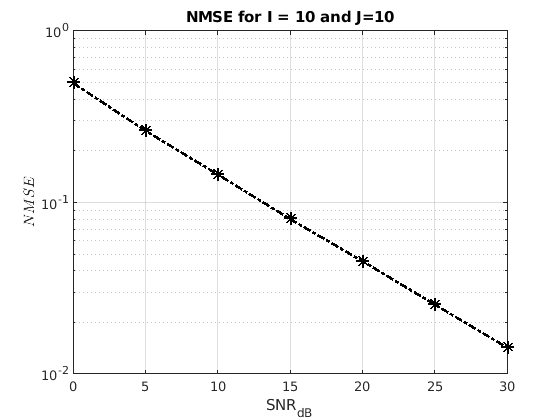

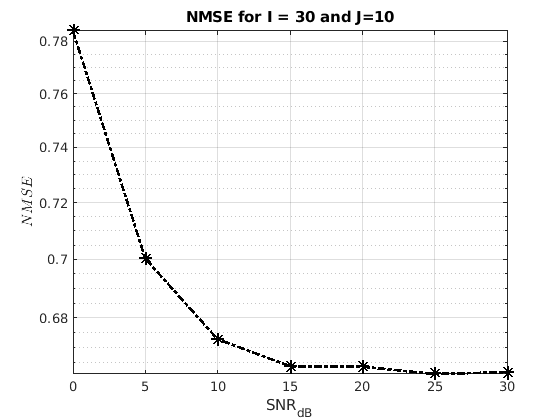

title_text = ["10","30"];
for index=1:2
    fig = figure();
    ax = gca();
    plot(snr_set, all_nmse(index,:), 'LineWidth', 4, 'Color', 'black',"LineStyle","-.","Marker","*","MarkerSize",18);
    title(append("NMSE for I = ", title_text(index), " and J=10"));
    ax.FontName = 'Times New Roman';
    ax.FontSize = 20;
    ax.YAxis.Scale='log';
    ax.XAxis.Label.String = 'SNR_{dB}';
    ax.YAxis.Label.String = '$$NMSE$$';
    ax.YAxis.Label.Interpreter = 'latex';
    grid on;
end

#### Conclusion:

The LSKRF can retrieve the matrix X properly when the number of lines in A and B is equal (In this case, when I=J=10). However, when I is different from J, the LSKRF cannot achieve the same performance.